# Temperature response of Rubisco activation state in rice

## Data Extraction

Plot the wild-type curve from Fig 4A of [Makino and Sage (2007)](https://academic.oup.com/pcp/article/48/10/1472/1938331):

Define the data points:

% % Use manual estimates
% X = [16,20,25,32,37,41]; % Temperature
% Y = [85,85,80,73,69,48]; % Activation state (%)

% Load data from .csv file compiled from automated tools - e.g. GraphReader, PlotDigitizer or WebPlotDigitizer
% These points are from Plot Digitizer:
% plot_data = readmatrix("Fig_4A-plot-data.csv");

% These points are from Web Plot Digitizer
plot_data = readmatrix("Fig_4A_plot_data_2.csv");

% Convert activation percentage to decimal
plot_data(:,2) = plot_data(:,2)/100;

% Set variables
X = plot_data(:,1);
Y = plot_data(:,2); 

Plot points:

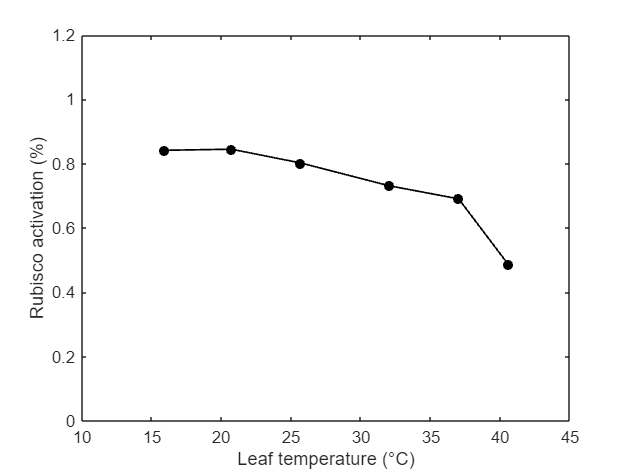

figure
plot(X,Y,'-o',...
    'Color','black',...
    'LineWidth',1,...
    'MarkerSize',5,...
    'MarkerEdgeColor','black',...
    'MarkerFaceColor','black')
xlim([10 45]);
ylim([0 1.2]);
xlabel('Leaf temperature (°C)');
ylabel('Rubisco activation (%)');

%set(gcf, 'PaperOrientation', 'landscape');
%print(gcf,fullfile('Outputs/rice_params/graphs',"Temp_vs_RuAct_new"),'-djpeg');

## Polynomial curve fitting

Use polyfit to fit a polynomial model, obtaining parameter (P) and error (S) estimates:

[polyfit_model2,S2] = polyfit(X,Y,2);
[polyfit_model3,S3] = polyfit(X,Y,3);

Evaluate the polynomial model fits with standard error estimates (Delta): 

[Y1,Delta1] = polyval(polyfit_model2,X,S2);
[Y2,Delta2] = polyval(polyfit_model3,X,S3);

Use symbolic variables to construct polynomial equations

Define a symbolic variable:

syms x; 

Convert polynomial coefficients to symbolic polynomial form with a conversion of exact rational fractions to 4 d.p. using vpa (variable-precision arithmetic):

polyfit2_equation = vpa(poly2sym(polyfit_model2, x),4);
polyfit3_equation = vpa(poly2sym(polyfit_model3, x),4);

Convert symbolic expressions to LaTeX strings to be added as plot legends: 

polyfit2_str = latex(polyfit2_equation);
polyfit3_str = latex(polyfit3_equation);
polyfit2_label = sprintf('Quadratic: $%s$', polyfit2_str);
polyfit3_label = sprintf('Cubic: $%s$', polyfit3_str);

Plot the models on top of the data points:

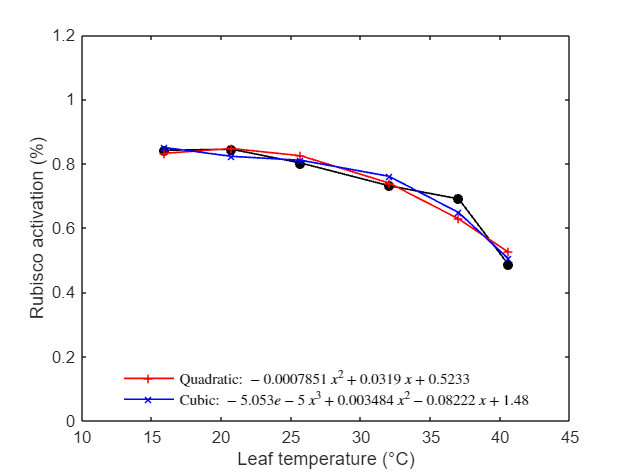

figure
% Plot data points
plot(X,Y,'-o',...
    'Color','black',...
    'LineWidth',1,...
    'MarkerSize',5,...
    'MarkerEdgeColor','black',...
    'MarkerFaceColor','black',...
    'HandleVisibility', 'off') % Exclude data from legend
hold on
% Plot model fit for second order polynomial in red
plot(X,Y1,'-+',...
    'Color','r',...
    'LineWidth',1,...
    'MarkerSize',5,...
    'MarkerEdgeColor','r',...
    'MarkerFaceColor','r')
hold on 
% Plot model fit for third order polynomial in blue
plot(X,Y2,'-x', ...
    'Color','b',...
    'LineWidth',1,...
    'MarkerSize',5,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor','b')
hold off
% Add labels 
xlim([10 45]);
ylim([0 1.2]);
xlabel('Leaf temperature (°C)');
ylabel('Rubisco activation (%)');
% Add legend
legend({polyfit2_label, polyfit3_label}, ...
    'Interpreter', 'latex', 'Location', 'best', 'Box', 'off');

% Adjust figure properties and export
%set(gcf, 'PaperOrientation', 'landscape');
%print(gcf,fullfile('Outputs/rice_params/graphs',"Temp_vs_RuAct_new_fits"),'-djpeg');

## Evaluation of fitted models

Calculate residuals for each of the fits by subtracting predicted from observed values:

residuals_poly2 = Y - Y1;  
residuals_poly3 = Y - Y2;  

Plot residuals against temperature for second-order polynomial fit:

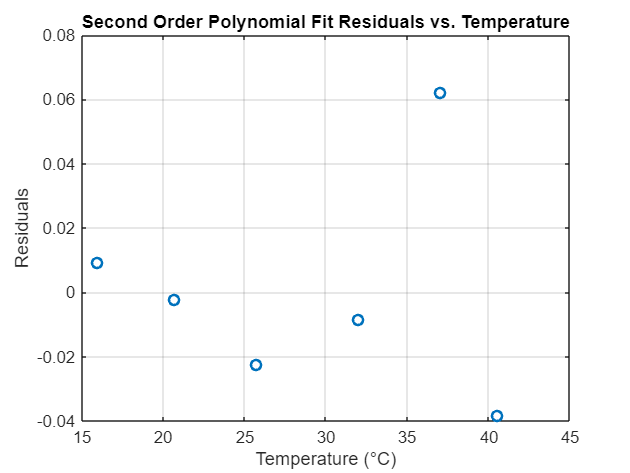

figure;
plot(X, residuals_poly2, 'o', 'LineWidth', 1.5);
xlabel('Temperature (°C)');
ylabel('Residuals');
title('Second Order Polynomial Fit Residuals vs. Temperature');
grid on;

Plot residuals against temperature for third-order polynomial fit:

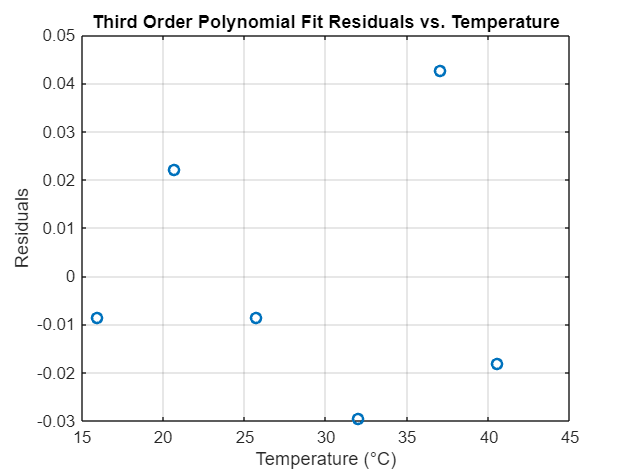

figure;
plot(X, residuals_poly3, 'o', 'LineWidth', 1.5);
xlabel('Temperature (°C)');
ylabel('Residuals');
title('Third Order Polynomial Fit Residuals vs. Temperature');
grid on;

Plot residuals against fitted values for second-order polynomial fit:

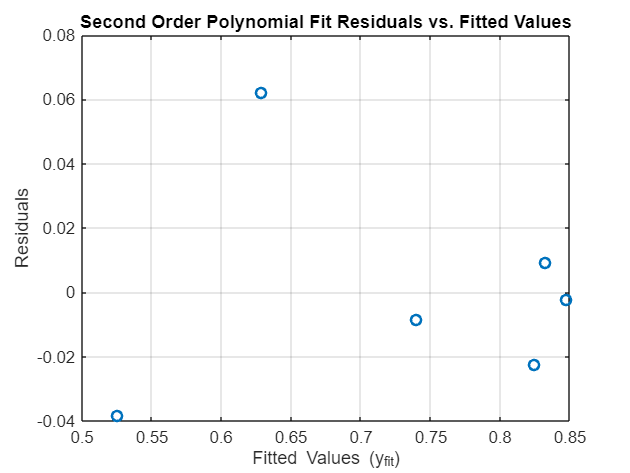

figure;
polyfit2_residualsT_plot = plot(Y1, residuals_poly2, 'o', 'LineWidth', 1.5);
xlabel('Fitted Values (y_{fit})');
ylabel('Residuals');
title('Second Order Polynomial Fit Residuals vs. Fitted Values');
grid on;

Plot residuals against fitted values for third-order polynomial fit:

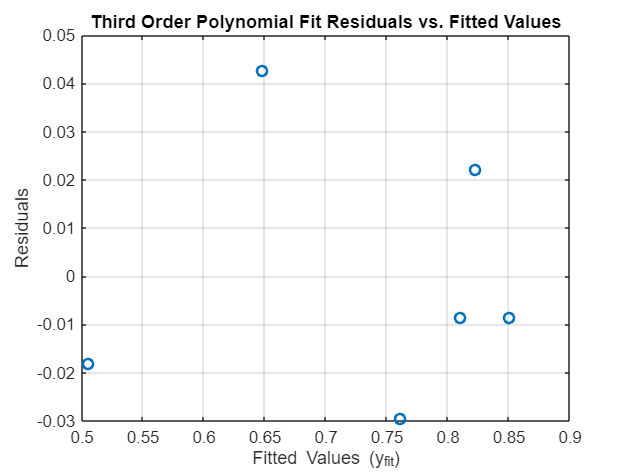

figure;
polyfit3_residualsT_plot = plot(Y2, residuals_poly3, 'o', 'LineWidth', 1.5);
xlabel('Fitted Values (y_{fit})');
ylabel('Residuals');
title('Third Order Polynomial Fit Residuals vs. Fitted Values');
grid on;

Calculate total and residual sum of squares:

SST = sum((Y - mean(Y)).^2)            % Total sum of squares

SST = 0.0913

SSR1 = sum(residuals_poly2.^2)         % Residual sum of squares, quadratic model

SSR1 = 0.0060

SSR2 = sum(residuals_poly3.^2)         % Residual sum of squares, cubic model

SSR2 = 0.0037

Calculate mean squared error for each fit:

squared_residuals_2 = residuals_poly2.^2

squared_residuals_2 =     0.0001
    0.0000
    0.0005
    0.0001
    0.0039
    0.0015


squared_residuals_3 = residuals_poly3.^2

squared_residuals_3 =     0.0001
    0.0005
    0.0001
    0.0009
    0.0018
    0.0003


mse_polyfit2 = mean(squared_residuals_2)

mse_polyfit2 = 9.9847e-04

mse_polyfit3 = mean(squared_residuals_3)

mse_polyfit3 = 6.0899e-04

Calculate variance of residuals:

% Variance of residuals (sigma^2)
sigma2_poly2 = var(residuals_poly2)

sigma2_poly2 = 0.0012

sigma2_poly3 = var(residuals_poly3)

sigma2_poly3 = 7.3079e-04

Set n = number of data points and number of parameters as degree of the polynomial + 1

n = length(Y);
numParams_2 = 3;
numParams_3 = 4; 

Calculate log-likelihoods for the polynomial models:

logLikelihood_2 = -n/2 * log(2 * pi * sigma2_poly2) - SSR1 / (2 * sigma2_poly2);
logLikelihood_3 = -n/2 * log(2 * pi * sigma2_poly3) - SSR2 / (2 * sigma2_poly3);

Calculate Akaike Information Criterion (AIC) for the fitted models:

aic_polyfit2 = 2 * numParams_2 - 2 * logLikelihood_2

aic_polyfit2 = -18.3345

aic_polyfit3 =  2 * numParams_3 - 2 * logLikelihood_3

aic_polyfit3 = -19.3011